# Activity 6: Morphological Operations 

## Activity 6.1. Set Theory

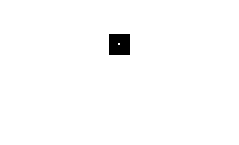

%A 5x5 square 
clear; close;
s = Square(10,11,10,11);
imshow(s); 

%
clear; close;
Hollow(6, 15, 8, 13);

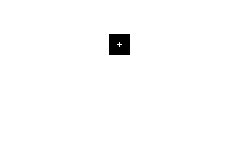

clear;close;
g=Cross(9, 13, 11, 11);
imshow(g);

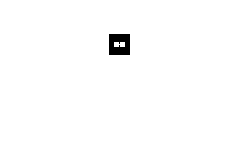

clear;close;
imshow(Dumbell( 11, 11,10,12, 9,13));

%structuring elements
SE1 = strel([0 0 0; 0 1 1; 0 1 1]); %2x2 square
SE2 = strel([0 0 0; 0 1 1; 0 0 0]); %2x1 line
SE3 = strel("square", 5);           %5x5 square


#### EROSION

#### A 5x5 square

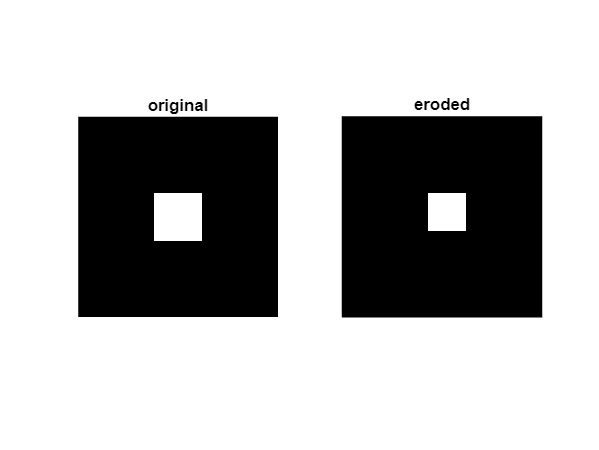

close; clear;
Erode(Square(9,13,9,13), strel([0 0 0; 1 1 0; 1 1 0]));

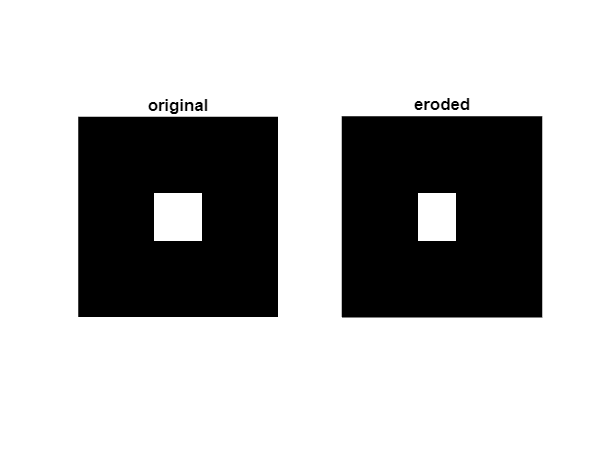

close;clear;
Erode(Square(9,13,9,13), strel([0 0 0; 0 1 1; 0 0 0]));

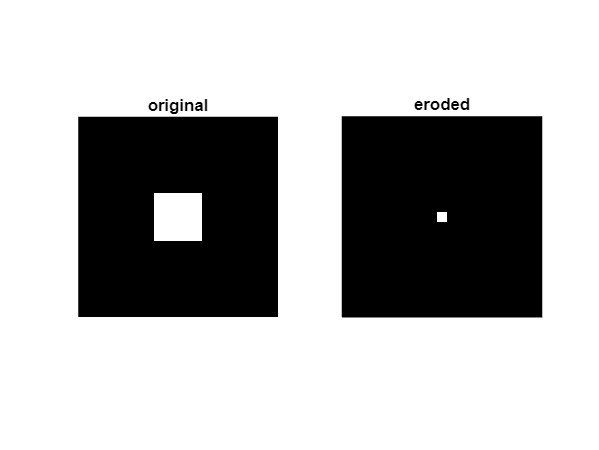

close;clear;
Erode(Square(9,13,9,13), strel("square", 5));

#### A hollow 10x10 square

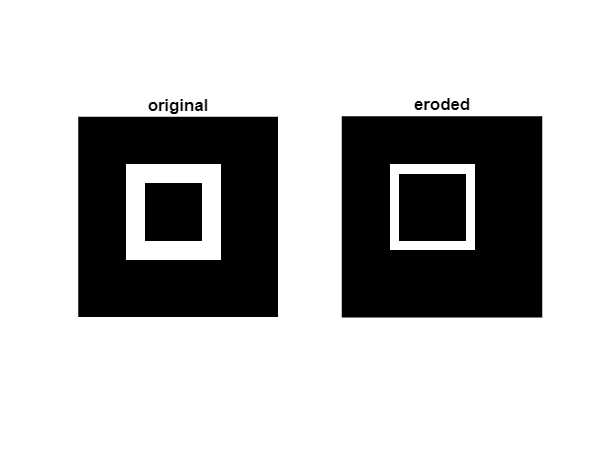

close;clear;
Erode(Hollow(6, 15, 8, 13), strel([0 0 0; 0 1 1; 0 1 1]));

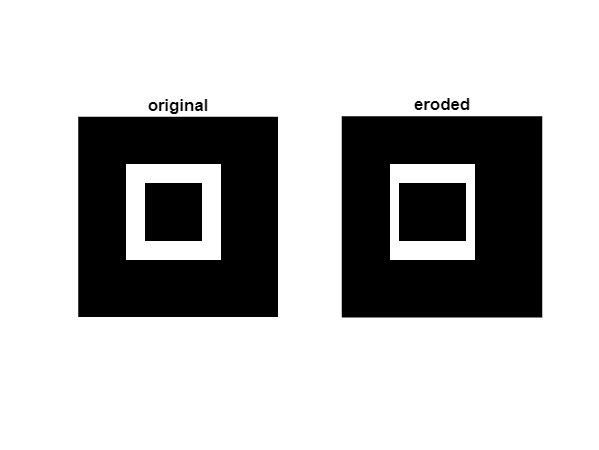

close; clear;
Erode(Hollow(6, 15, 8, 13), strel([0 0 0; 0 1 1; 0 0 0]));

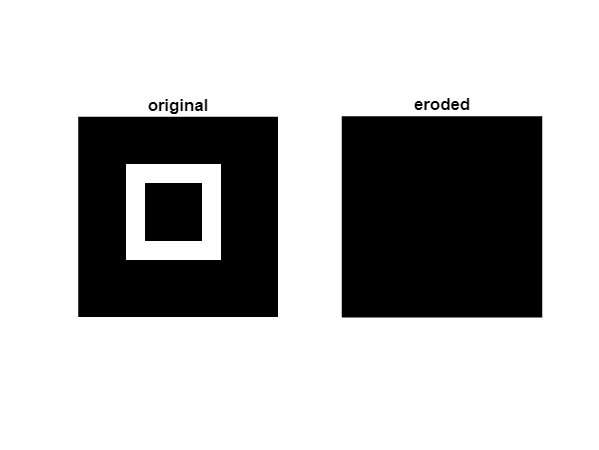

clear;close;
Erode(Hollow(6, 15, 8, 13), strel("square", 5));

#### A plus sign

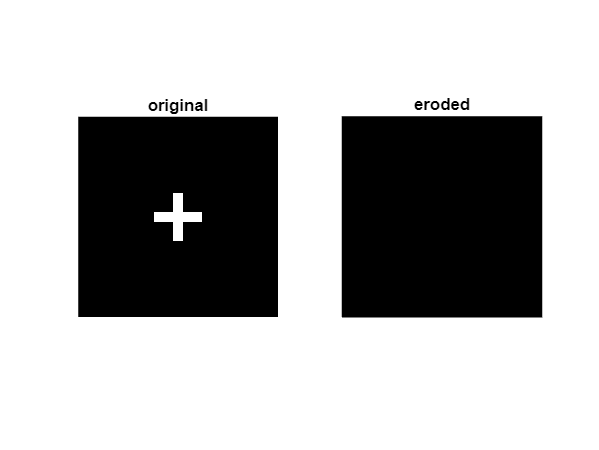

clear;close;
Erode(Cross(9, 13, 11, 11), strel([0 0 0; 0 1 1; 0 1 1]));

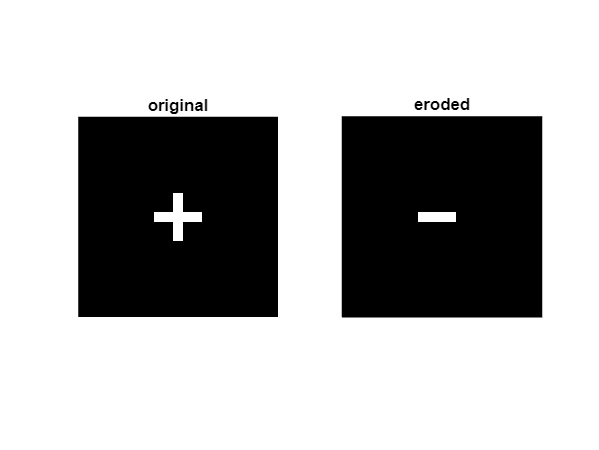

clear;close;
Erode(Cross(9, 13, 11, 11), strel([0 0 0; 0 1 1; 0 0 0]));

clear;close;
Erode(Cross(9, 13, 11, 11), strel("square", 5));

#### A dumbbell

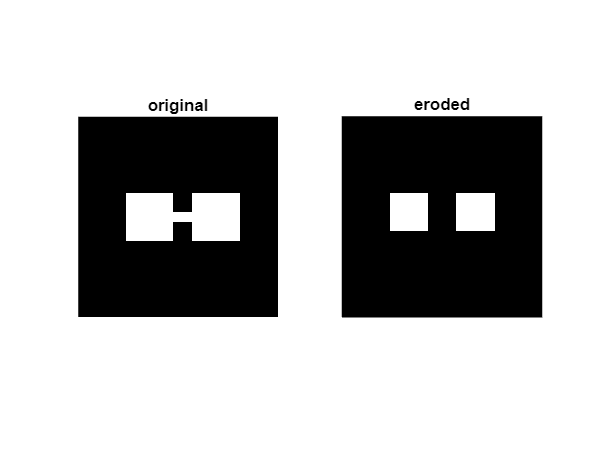

clear;close;
Erode(Dumbell( 11, 11,10,13, 9,13), strel([0 0 0; 0 1 1; 0 1 1]));

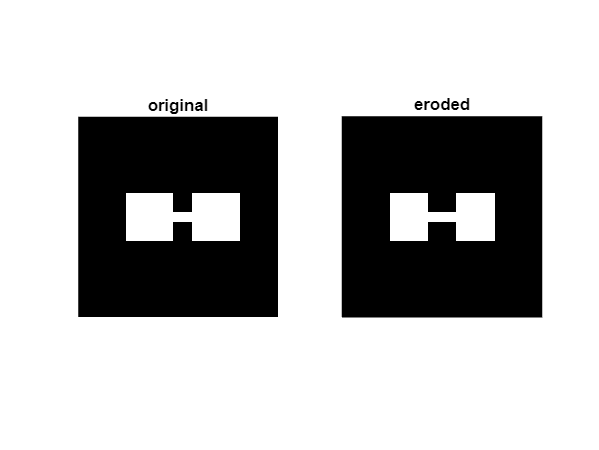

clear;close;
Erode(Dumbell( 11, 11,10,13, 9,13), strel([0 0 0; 0 1 1; 0 0 0]));

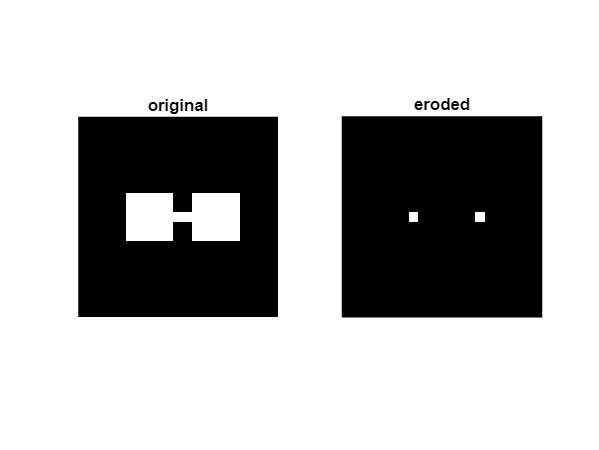

clear;close;
Erode(Dumbell( 11, 11,10,13, 9,13), strel("square", 5));

### DILATION

#### A 5x5 square

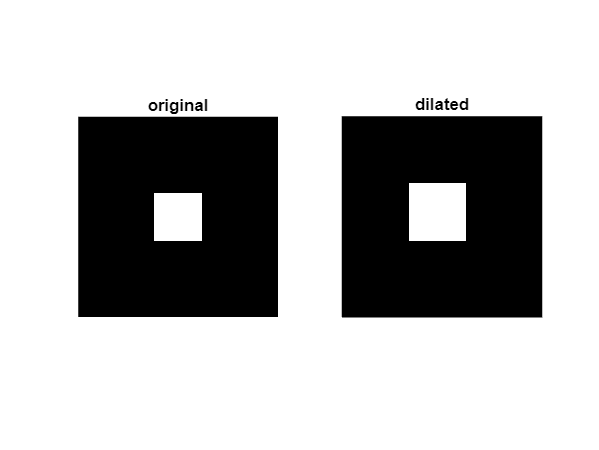

close; clear;
Dilate(Square(9,13,9,13), strel([1 1 0; 1 1 0; 0 0 0]));

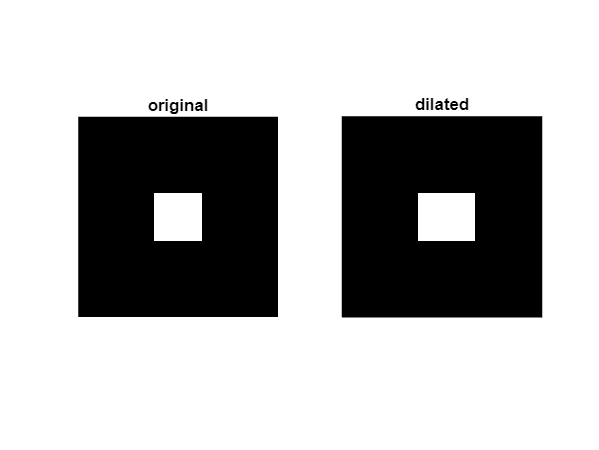

close;clear;
Dilate(Square(9,13,9,13), strel([0 0 0; 0 1 1; 0 0 0]));

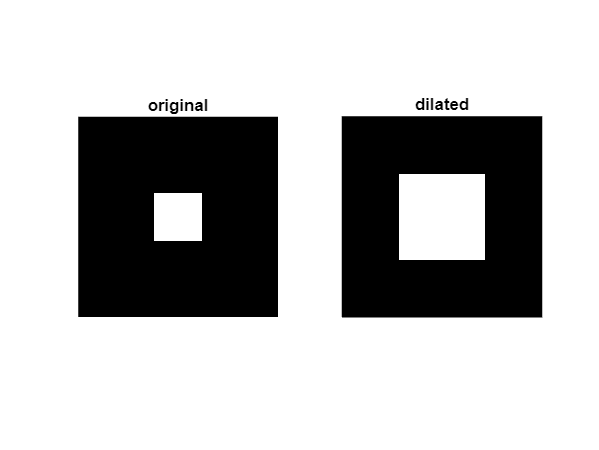

close;clear;
Dilate(Square(9,13,9,13), strel("square", 5));

#### A hollow 10x10 square, 2 boxes thick

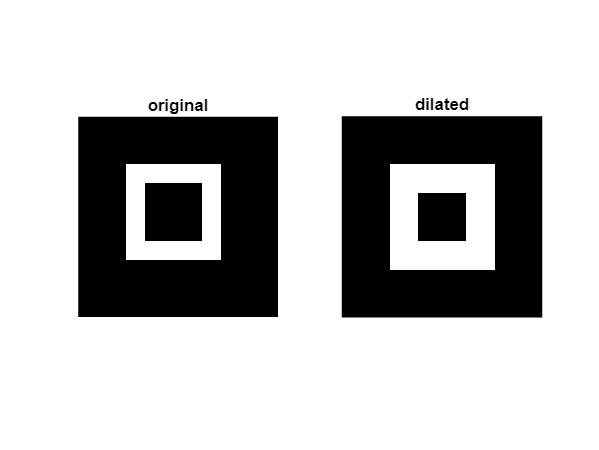

close;clear;
Dilate(Hollow(6, 15, 8, 13), strel([0 0 0; 0 1 1; 0 1 1]));

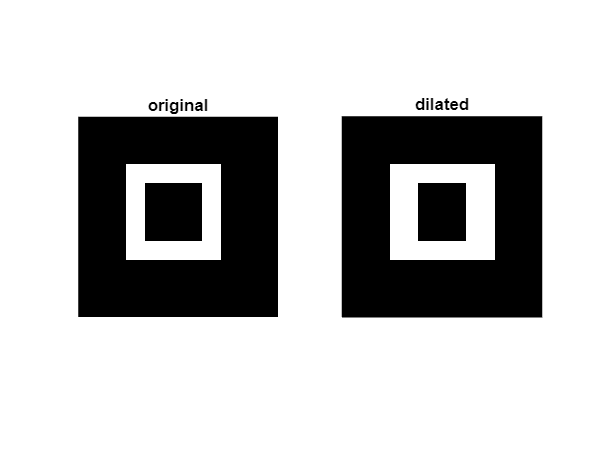

close; clear;
Dilate(Hollow(6, 15, 8, 13), strel([0 0 0; 0 1 1; 0 0 0]));

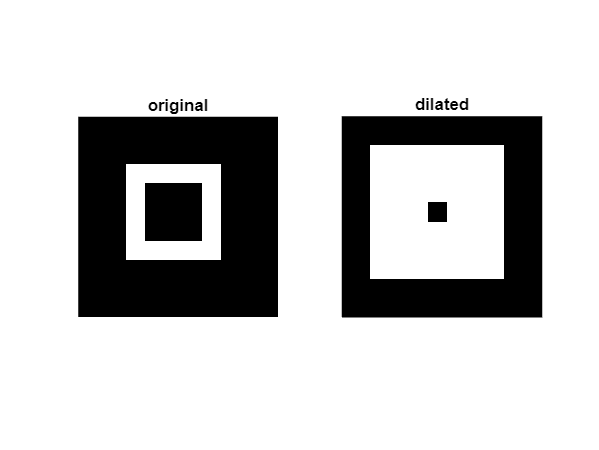

clear;close;
Dilate(Hollow(6, 15, 8, 13), strel("square", 5));

#### A plus sign

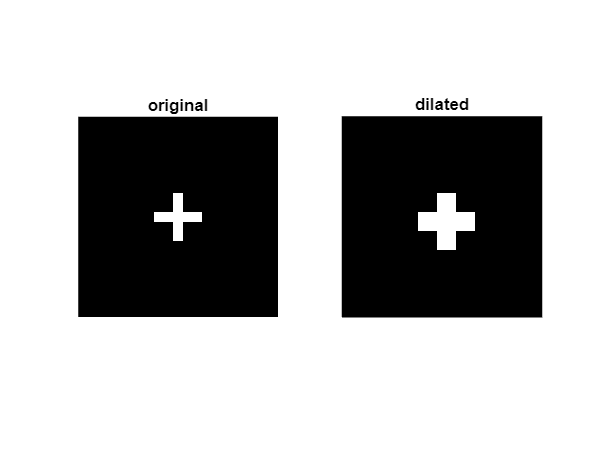

clear;close;
Dilate(Cross(9, 13, 11, 11), strel([0 0 0; 0 1 1; 0 1 1]));

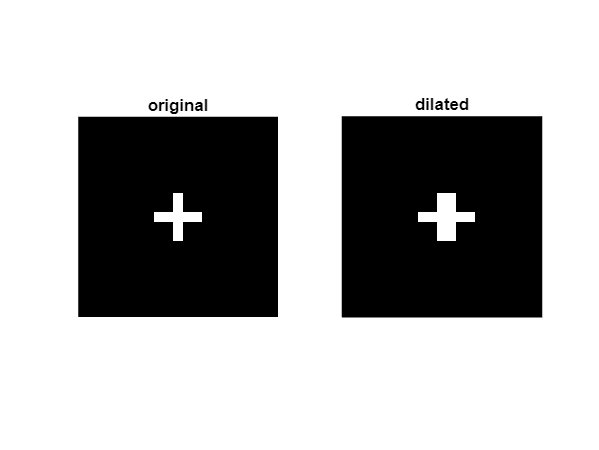

clear;close;
Dilate(Cross(9, 13, 11, 11), strel([0 0 0; 0 1 1; 0 0 0]));

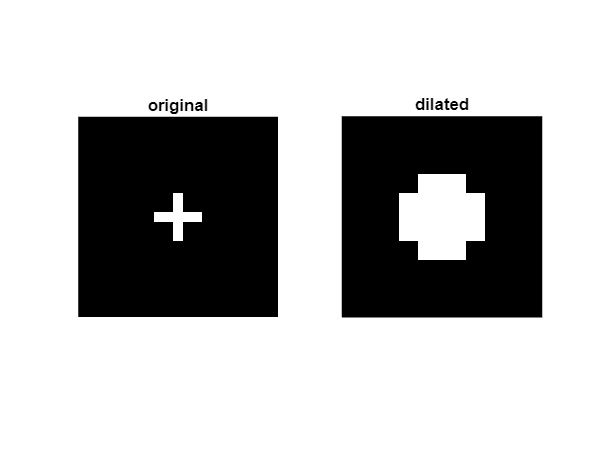

clear;close;
Dilate(Cross(9, 13, 11, 11), strel("square", 5));

#### A dumbbell

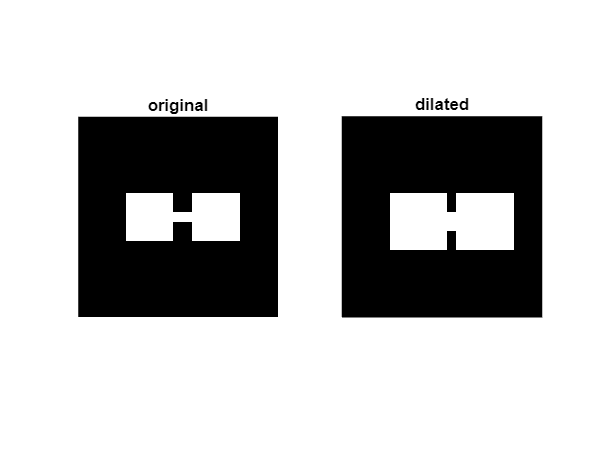

clear;close;
Dilate(Dumbell( 11, 11,10,13, 9,13), strel([0 0 0; 0 1 1; 0 1 1]));

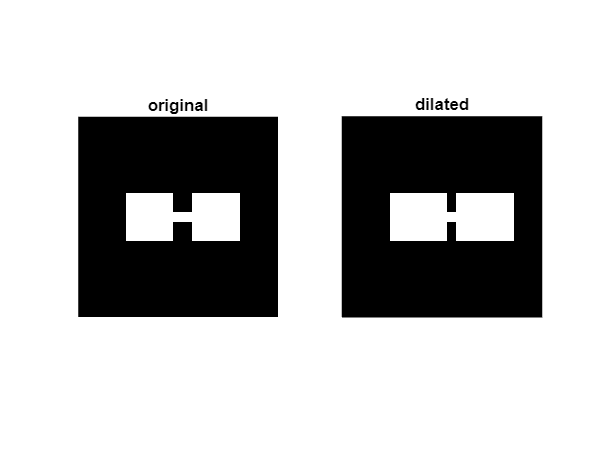

clear;close;
Dilate(Dumbell( 11, 11,10,13, 9,13), strel([0 0 0; 0 1 1; 0 0 0]));

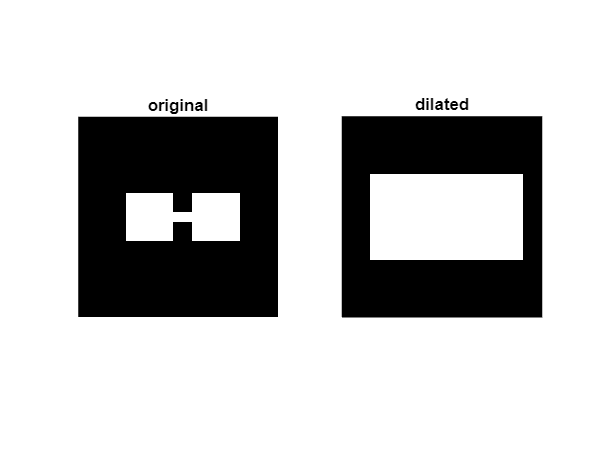

clear;close;
Dilate(Dumbell( 11, 11,10,13, 9,13), strel("square", 5));

## ACTIVITY 6.2. 

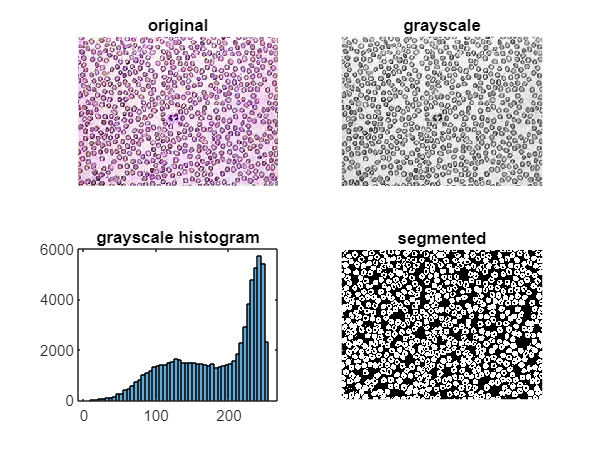

clear;close;

I = imread("blood.jpg");
Igray = rgb2gray(I);
figure(1);
subplot(2,2,1); imshow(I); axis image; title("original");
subplot(2,2,2); imshow(Igray); axis image; title("grayscale");
subplot(2,2,3); histogram(Igray); title("grayscale histogram");
subplot(2,2,4); BW = and(Igray<200, Igray>0); imshow(BW); title("segmented");

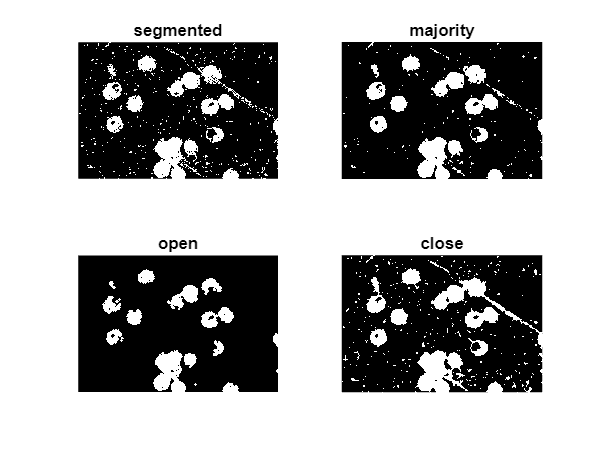

Morpho("malaria(1).jpeg", 100, 164, strel("disk", 2));

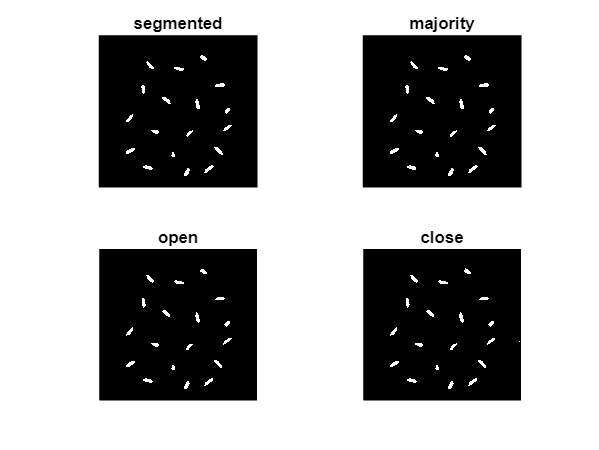

Morpho("rice.jpg", 164, 256, strel("disk", 1));

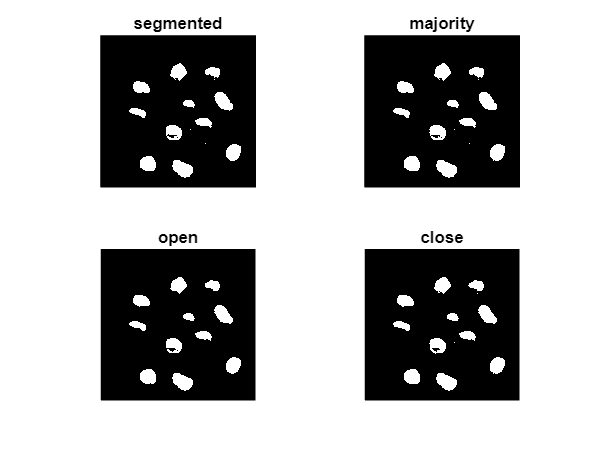

Morpho("nuts (2).jpg", 164, 256, strel("disk", 5));

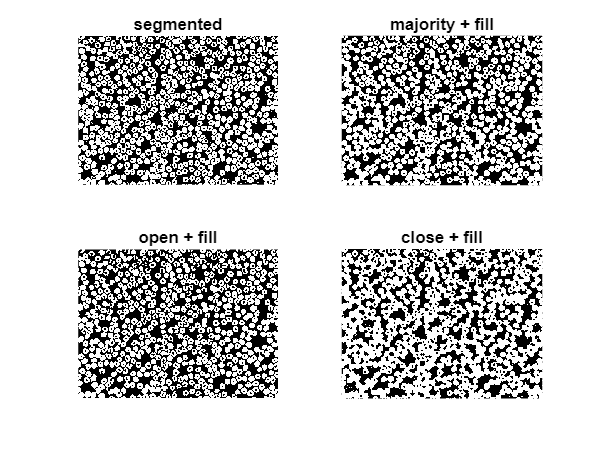

clear;close;
Morphofill("blood.jpg", 0, 200, strel("disk", 1));

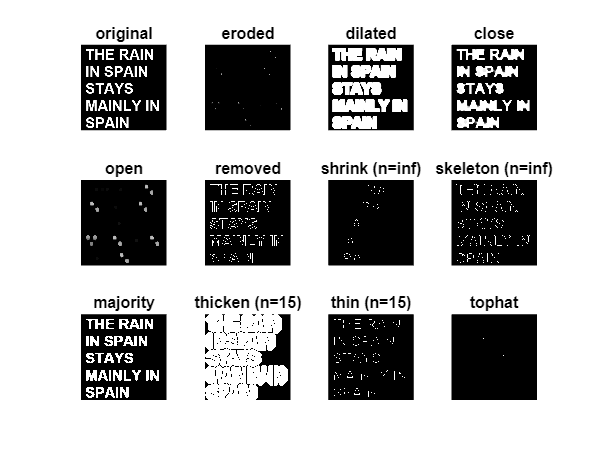

clear;close;
Morphol("THERAIN.tif");

function A = Square(n1,m1,n2,m2) 
    A = zeros(21,21);
    A(n1:m1, n2:m2) = 1; 
end
function A = Hollow(n1,m1,n2,m2)
    A = zeros(21,21);
    A(n1:m1, n1:m1) = 1;
    A(n2:m2, n2:m2) =0;
end
function A = Cross(n1,m1,n2,m2)
    A = zeros(21,21);
    A(n1:m1, n2:m2) = 1;
    A(n2:m2, n1:m1) = 1;
end
function A = Dumbell(n1, m1, n2, m2, n3, m3)
    A = zeros(21,21);
    A(n1:m1, n2:m2)=1;
    A(n3:m3, (n2-4):n2) = 1;
    A(n3:m3, m2:(m2+4)) = 1;
end
function [a,b] = Erode(image, struc)
    er = imerode(image, struc);
    a = subplot(1,2,1); imshow(image); title('original'); 
    b = subplot(1,2,2); imshow(er); title('eroded');
end
function [a,b] = Dilate(image, struc)
    er = imdilate(image, struc);
    a = subplot(1,2,1); imshow(image); title('original')
    b = subplot(1,2,2); imshow(er); title('dilated'); 
end
function [a,b,c,d] = Morpho(image,t1,t2, SE)
    I = imread(image);
    Igray = rgb2gray(I);
    BW = and(Igray<t2, Igray>t1);
    a = subplot(2,2,1); imshow(BW); title("segmented");
    b = subplot(2,2,2); 
    BW2 = bwmorph(BW, "majority"); 
    imshow(BW2);title("majority")
    c=subplot(2,2,3);
    BW3 = imopen(BW,SE); imshow(BW3); title("open");
    d=subplot(2,2,4);
    BW4 = imclose(BW, SE); imshow(BW4); title("close")
end 
function [a,b,c,d] = Morphofill(image,t1,t2, SE)
    I = imread(image);
    Igray = rgb2gray(I);
    BW = and(Igray<t2, Igray>t1);
    a = subplot(2,2,1); imshow(BW); title("segmented");
    b = subplot(2,2,2); 
    BW2 = bwmorph(BW, "majority"); 
    imshow(bwmorph(BW2,"fill"));title("majority + fill")
    c=subplot(2,2,3);
    BW3 = imopen(BW,SE); imshow(bwmorph(BW3, "fill")); title("open + fill");
    d=subplot(2,2,4);
    BW4 = imclose(BW, SE); imshow(bwmorph(BW4, "fill")); title("close + fill");
end 
function [a,b,c,d,e,f,g,h,i,j,k,l] = Morphol(image)
    I = rgb2gray(imread(image));
    a = subplot(3,4,1); imshow(I); title("original");
    b = subplot(3,4,2); imshow(imerode(I, strel("disk", 5))); title("eroded");
    c = subplot(3,4,3); imshow(imdilate(I, strel("disk", 5))); title("dilated");
    d = subplot(3,4,4); imshow(imclose(I,strel("disk", 5))); title("close");
    e = subplot(3,4,5); imshow(imopen(I, strel("disk", 5))); title("open");
    f = subplot(3,4,6); imshow(bwmorph(I, "remove")); title("removed");
    g = subplot(3,4,7); imshow(bwmorph(I, "shrink", Inf)); title("shrink (n=inf)");
    h = subplot(3,4,8); imshow(bwmorph(I, "skel",Inf)); title("skeleton (n=inf)");
    i = subplot(3,4,9); imshow(bwmorph(I, "majority")); title("majority");
    j = subplot(3,4,10); imshow(bwmorph(I, "thicken",15)); title("thicken (n=15)");
    k = subplot(3,4,11); imshow(bwmorph(I, "thin",15)); title("thin (n=15)");
    l = subplot(3,4,12); imshow(bwmorph(I, "tophat")); title("tophat");
end
